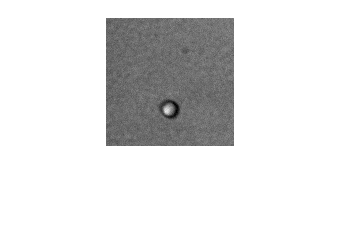

Error using getpts
Interruption during mouse point selection.

clear all;
close all;
warning('off','all');

folder = 'BioTransport/1_down/';
d=dir(append(folder,'*.tif'));
skip = 0;
magnificationFactor=1;
% framerate = 50;



% M = readmatrix('/imj_track_res/trackresults_1_down.txt');
% for i=1:numel(d) 
for i=1:100  
  if i == 1
      im=imread(append(folder , d(i).name));
      figure;
      imshow(im);
      [xi,yi] = getpts;
      close all;
%       pause;
%       Iblur = imgaussfilt(im,3);
%       I{i}=double(Iblur);  
%       [centers, radii, metric] = imfindcircles(im,[3 30]);
%       centers=centers(1,:);
%       centers = M(i,2:3);
      centers = [xi(1) yi(1)];
      T1=table(i,centers);
      rawframes(:,:,:,i) = imresize(insertShape(im,'filled-circle',[centers(1),centers(2),2],'Color','red','LineWidth',1),magnificationFactor);
      
  else
      im=imread(append(folder , d(i).name));
      figure;
      imshow(im);
      title('slicenumber = ',i)
      [xi,yi] = getpts;
      close all;
%       centers = M(i,2:3);
      centers = [xi(1) yi(1)];
%       Iblur = imgaussfilt(im,3);
%       I{i}=double(Iblur);
%       [centers, radii, metric] = imfindcircles(im,[3 30]);
%       centers=centers(1,:);
      if isempty(centers) == 1
%          centers=zeros(1,2)
        im = cat(3, im, im, im);
        rawframes(:,:,:,i) = imresize(im,magnificationFactor);
        skip = skip+1;
        continue
      else
%         centers=centers(1,:);
%         centers = M(i,2:3);
        T1=[T1;table(i,centers)];
        rawframes(:,:,:,i) = imresize(insertShape(im,'filled-circle',[centers(1),centers(2),2],'Color','red','LineWidth',1),magnificationFactor);
      end
  end
end


name = split(d(i).folder,'/');
name = string(strcat(name(end-1),'/',name(end)));

% cookedframes = mat2gray(rawframes);
implay(rawframes);
v = VideoWriter(append(name,'_manual'),'MPEG-4');
v.Quality = 100;
v.FrameRate = 50;
open(v);
writeVideo(v,rawframes);
close(v)
% hold on;
% plot(50,100, 'r+', 'MarkerSize', 30, 'LineWidth', 2);
% uiwait(msgbox('Locate the point'));
% [x,y] = ginput(1);
% hold on; % Prevent image from being blown away.
% plot(x,y,'r+', 'MarkerSize', 50);

% writetable(T1 ,'group4_1.csv');
arr=table2array(T1);
X=arr(:,2);Yp=127-arr(:,3);Y=arr(:,3);
% XY = (arr(t,2),arr(t,2));
figure;
plot(X,Yp,'b');
xlabel('x(pixel=0.11um)');
ylabel('y(pixel=0.11um)');
title('Moving Path');
grid on;
saveas(gcf,append(name,'_manual_movingpath.png'));


xsize=size(X,1);
ysize=size(Y,1);
datasize=min(xsize,ysize);

dt=1;%init loop var
msd_total=[];
y1=[];
% figure;
while (dt<datasize)
    for i=1:datasize-dt
        dx(i,1)=X(i+dt,1)-X(i,1);
        dy(i,1)=Y(i+dt,1)-Y(i,1);
    end
    msd=sum(dx.^2+dy.^2)/(datasize-dt);
    msd_total=[msd_total,msd];
    dx=[];
    dy=[];
%     plot(dt,msd,'b*');hold on;
    dt=dt+1;
end
% csvwrite('group4_2.csv',msd_total');
% ds = mat2dataset(msd_total);
% % % mdl = fitlm(msd_total
% l = (1:length(msd_total));
% k = polyfit(sort(msd_total),l,1);
% for i=1:length(msd_total)
%     y =k(1)*i+k(2);
%     y1 =[y1,y];
% end
% plot(y1,'b-');

figure;
len = length(msd_total);
x = (1:len)';
y_new = msd_total';
% b = x\y_new;
% yCalc = b*x;
scatter(x,y_new);
hold on;
% plot(x,yCalc,"LineWidth",2);

xx = [ones(length(x),1) x];
b1 = xx\y_new;
yCalc1 = b1(2)*x+b1(1);
plot(x,yCalc1,'--',"LineWidth",2);


% if mod(length(x),50)==0
%     new_xticks=0:framerate/2:length(x);
% else
%     new_xticks=[0:framerate/2:length(x),length(x)];
% end
format bank;
% gap=framerate/2;
new_xticks=0:25:200;
% new_xtickslabel=new_xticks./framerate;
xticks(new_xticks);
xticklabels({0:0.5:4});
title('Mean Square Displacement');
xlabel('time(sec)');
ylabel('MSD');
leg =legend('MSD','linear regression','Location','best');
b=num2str(b1(2));
txt = strcat('correlation coefficient=',b);
title(leg,txt);

skip;
if skip > numel(d)*0.3 
    printf('Skipped too much, This Result is not reliable');
end
saveas(gcf,append(name,'_manual_MSD.png'));
warning('on','all');






